# **PMM PI Control Implementation**

clear
clc
clf
rng default

## Load Data

pmm = load("picontrol_PMM_run4.mat");

## PMM

% run 1 -> using NMP settings to control MP

t_pmm = pmm.PMM.get("eTape1").Values.Time;
h1_pmm = pmm.PMM.get("eTape1").Values.Data;
h2_pmm = pmm.PMM.get("eTape2").Values.Data;
SP1_pmm = pmm.PMM.get("SP1").Values.Data;
SP2_pmm = pmm.PMM.get("SP2").Values.Data;
v1_pmm = pmm.PMM.get("v1").Values.Data;
v2_pmm = pmm.PMM.get("v2").Values.Data;
e1_pmm = pmm.PMM.get("error1").Values.Data;
e2_pmm = pmm.PMM.get("error2").Values.Data;

% edit data
pmm_SP2_step1 = find(SP2_pmm == 18, 1, "first");
pmm_SP2_step2 = find(SP2_pmm == 17, 1, "first");

% Calculate time shift
if pmm_SP2_step1 > 1
    time_shift = t_pmm(pmm_SP2_step2 + 1) - t_pmm(pmm_SP2_step1 - 1);
else
    time_shift = t_pmm(pmm_SP2_step2 + 1) - t_pmm(1);
end

% Create keep index
keep_idx = true(length(t_pmm), 1);
keep_idx(pmm_SP2_step1:pmm_SP2_step2) = false;

% Delete data
t_pmm = t_pmm(keep_idx);
h1_pmm = h1_pmm(keep_idx);
h2_pmm = h2_pmm(keep_idx);
SP1_pmm = SP1_pmm(keep_idx);
SP2_pmm = SP2_pmm(keep_idx);
v1_pmm = v1_pmm(keep_idx);
v2_pmm = v2_pmm(keep_idx);
e1_pmm = e1_pmm(keep_idx);
e2_pmm = e2_pmm(keep_idx);

% Normalize time
if pmm_SP2_step1 > 1
    t_pmm(pmm_SP2_step1:end) = t_pmm(pmm_SP2_step1:end) - time_shift;
else
    t_pmm = t_pmm - time_shift;
end

## PMM Total

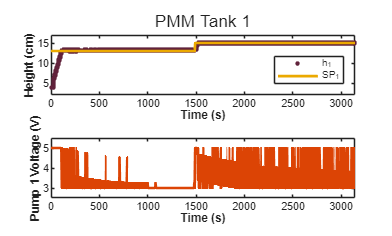

fig1 = figure(1);
f1 = tiledlayout(fig1, 2, 1);
title(f1, "PMM Tank 1")

nexttile
plot(t_pmm, h1_pmm, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_pmm, SP1_pmm, "LineWidth", 2, "Color", "#eba900")
legend("h_1", "SP_1", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t_pmm(end)])
ylim([2 17])
hold off

nexttile
plot(t_pmm, v1_pmm, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 1 Voltage (V)", "FontWeight", "bold")
xlim([0 t_pmm(end)])
ylim([2.5 5.5])

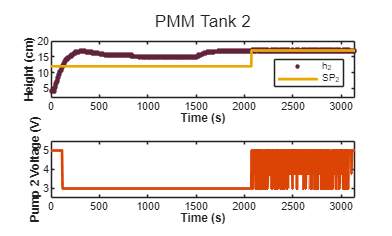


fig2 = figure(2);
f2 = tiledlayout(fig2, 2, 1);
title(f2, "PMM Tank 2")

nexttile
plot(t_pmm, h2_pmm, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_pmm, SP2_pmm, "LineWidth", 2, "Color", "#eba900")
legend("h_2", "SP_2", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t_pmm(end)])
ylim([2 20])
hold off

nexttile
plot(t_pmm, v2_pmm, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 2 Voltage (V)", "FontWeight", "bold")
xlim([0 t_pmm(end)])
ylim([2.5 5.5])

## PMM After SP 1

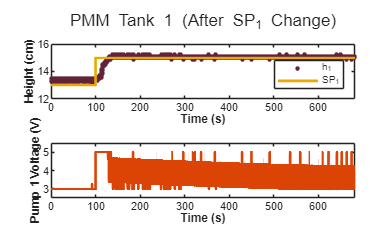

SP1_step = find(SP1_pmm == 15, 1, "first");
SP2_step = find(SP2_pmm == 17, 1, "first");
t_1 = t_pmm((SP1_step - 1000):(SP2_step - 1)) - t_pmm(SP1_step - 1000);
h1_1 = h1_pmm((SP1_step - 1000):(SP2_step - 1));
h2_1 = h2_pmm((SP1_step - 1000):(SP2_step - 1));
SP1_1 = SP1_pmm((SP1_step - 1000):(SP2_step - 1));
SP2_1 = SP2_pmm((SP1_step - 1000):(SP2_step - 1));
v1_1 = v1_pmm((SP1_step - 1000):(SP2_step - 1));
v2_1 = v2_pmm((SP1_step - 1000):(SP2_step - 1));

fig3 = figure(3);
f3 = tiledlayout(fig3, 2, 1);
title(f3, "PMM Tank 1 (After SP_1 Change)")

nexttile
plot(t_1, h1_1, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_1, SP1_1, "LineWidth", 2, "Color", "#eba900")
legend("h_1", "SP_1", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t_1(end)])
ylim([12 16])
hold off

nexttile
plot(t_1, v1_1, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 1 Voltage (V)", "FontWeight", "bold")
xlim([0 t_1(end)])
ylim([2.5 5.5])
hold off

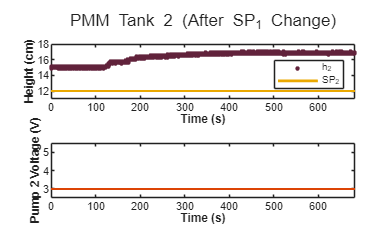


fig4 = figure(4);
f4 = tiledlayout(fig4, 2, 1);
title(f4, "PMM Tank 2 (After SP_1 Change)")

nexttile
plot(t_1, h2_1, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_1, SP2_1, "LineWidth", 2, "Color", "#eba900")
legend("h_2", "SP_2", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t_1(end)])
ylim([11 18])
hold off

nexttile
plot(t_1, v2_1, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 2 Voltage (V)", "FontWeight", "bold")
xlim([0 t_1(end)])
ylim([2.5 5.5])

## PMM After SP 2

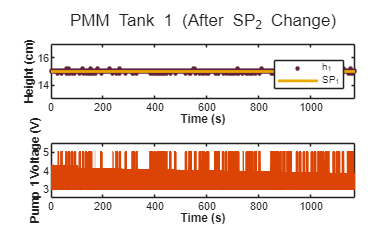

t_2 = t_pmm((SP2_step - 1000):end) - t_pmm(SP2_step - 1000);
h1_2 = h1_pmm((SP2_step - 1000):end);
h2_2 = h2_pmm((SP2_step - 1000):end);
SP1_2 = SP1_pmm((SP2_step - 1000):end);
SP2_2 = SP2_pmm((SP2_step - 1000):end);
v1_2 = v1_pmm((SP2_step - 1000):end);
v2_2 = v2_pmm((SP2_step - 1000):end);

fig5 = figure(5);
f5 = tiledlayout(fig5, 2, 1);
title(f5, "PMM Tank 1 (After SP_2 Change)")

nexttile
plot(t_2, h1_2, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_2, SP1_2, "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_1", "SP_1", "Location", "southeast")
xlim([0 t_2(end)])
ylim([13 17])
hold off

nexttile
plot(t_2, v1_2, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 1 Voltage (V)", "FontWeight", "bold")
xlim([0 t_2(end)])
ylim([2.5 5.5])

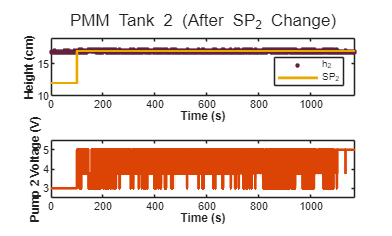



fig6 = figure(6);
f6 = tiledlayout(fig6, 2, 1);
title(f6, "PMM Tank 2 (After SP_2 Change)")

nexttile
plot(t_2, h2_2, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_2, SP2_2, "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_2", "SP_2", "Location", "southeast")
xlim([0 t_2(end)])
ylim([10 19])
hold off

nexttile
plot(t_2, v2_2, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 2 Voltage (V)", "FontWeight", "bold")
xlim([0 t_2(end)])
ylim([2.5 5.5])

## Metrics

% ITAE after SP1 change
t_1_ITAE = t_pmm(SP1_step:(SP2_step - 1)) - t_pmm(SP1_step);
e1_1 = e1_pmm(SP1_step:(SP2_step - 1));
e2_1 = e2_pmm(SP1_step:(SP2_step - 1));
SP1_1 = SP1_pmm(SP1_step:(SP2_step - 1));
SP2_1 = SP2_pmm(SP1_step:(SP2_step - 1));

% plot(t_1_ITAE, e1_1)
% plot(t_1_ITAE, h2_pmm((find(SP1 == SP1_step, 1, "first")):SP2_idx_2), t_1_ITAE, SP2_1)

% settling window
tolerance1 = 2/100;
ub1 = tolerance1*SP1_1(1); % upper bound
lb1 = -tolerance1*SP1_1(1); % lower bound
st = 150; % settling time
dt = 0.1; % sample time
st_samples = st/dt; % number of samples (i.e. rows in matrix)
e1_1_bounds = (e1_1 >= lb1) & (e1_1 <= ub1); % true or false matrix (1 or 0) to determine 150 s of settling

e1_1_settleidx = [];
for i = 1:(length(e1_1_bounds) - st_samples)
    if all(e1_1_bounds(i:i + st_samples))
        e1_1_settleidx = i; % i is the index where the level has settled and the 150 seconds are within the bounds
        break;
    end
end

% settling time for SP1 change
t1_1_settle = t_1_ITAE(e1_1_settleidx)

t1_1_settle = 24.3000


% time windows for calculating ITAE
window = 200;
idx1 = find(t_1_ITAE <= window);

% ITAE for SP1 change
ITAE1_1 = trapz(t_1_ITAE(idx1), t_1_ITAE(idx1).*abs(e1_1(idx1)))

ITAE1_1 = 2.0202e+03

ITAE2_1 = trapz(t_1_ITAE(idx1), t_1_ITAE(idx1).*abs(e2_1(idx1)))

ITAE2_1 = 8.6790e+04


% ISE for SP1 change
ISE1_1 = trapz(t_1_ITAE(idx1), (e1_1(idx1)).^2)

ISE1_1 = 35.7701

ISE2_1 = trapz(t_1_ITAE(idx1), (e2_1(idx1)).^2)

ISE2_1 = 3.3405e+03


% IAE for SP1 change
IAE1_1 = trapz(t_1_ITAE(idx1), abs(e1_1(idx1)))

IAE1_1 = 42.1055

IAE2_1 = trapz(t_1_ITAE(idx1), abs(e2_1(idx1)))

IAE2_1 = 810.4802

% ITAE after SP2 change
t_2_ITAE = t_pmm(SP2_step:end) - t_pmm(SP2_step);
e1_2 = e1_pmm(SP2_step:end);
e2_2 = e2_pmm(SP2_step:end);
SP1_2 = SP1_pmm(SP2_step:end);
SP2_2 = SP2_pmm(SP2_step:end);

% settling window
tolerance2 = 2/100;
ub2 = tolerance2*SP2_2(1); % upper bound
lb2 = -tolerance2*SP2_2(1); % lower bound
e2_2_bounds = (e2_2 >= lb2) & (e2_2 <= ub2); % true or false matrix (1 or 0) to determine 150 s of settling

e2_2_settleidx = [];
for j = 1:(length(e2_2_bounds) - st_samples)
    if all(e2_2_bounds(j:j + st_samples))
        e2_2_settleidx = j;
        break;
    end
end

% ITAE for SP2 change
% settling time for SP2 change
t2_2_settle = t_2_ITAE(e2_2_settleidx)

t2_2_settle = 0


% time window for calculating ITAE
idx2 = find(t_2_ITAE <= window);

% ITAE for SP1 change
ITAE1_2 = trapz(t_2_ITAE(idx2), t_2_ITAE(idx2).*abs(e1_2(idx2)))

ITAE1_2 = 1.3089e+03

ITAE2_2 = trapz(t_2_ITAE(idx2), t_2_ITAE(idx2).*abs(e2_2(idx2)))

ITAE2_2 = 1.5905e+03


% ISE for SP1 change
ISE1_2 = trapz(t_2_ITAE(idx2), (e1_2(idx2)).^2)

ISE1_2 = 1.3248

ISE2_2 = trapz(t_2_ITAE(idx2), (e2_2(idx2)).^2)

ISE2_2 = 1.6674


% IAE for SP1 change
IAE1_2 = trapz(t_2_ITAE(idx2), abs(e1_2(idx2)))

IAE1_2 = 13.0661

IAE2_2 = trapz(t_2_ITAE(idx2), abs(e2_2(idx2)))

IAE2_2 = 16.0596